# CAPÍTULO 06 - FLEXIÓN OBLICUA Y TRACCIÓN-COMPRESIÓN EXCÉNTRICA

Estudia la tensión longitudinal sobre una sección sometida a esfuerzo axial y dos momentos. Puedes introducir los momentos o calcularlos a partir de una fuerza excéntrica.

Dimensión: tensiones sobre una sección local 2D bajo flexión biaxial. Los esfuerzos pueden proceder de una estructura 3D del capítulo 7. El campo de color corresponde a la sección, no a una deformada espacial.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

contornos y signos describen material y huecos como en el capítulo 3. N es positivo en tracción. Los momentos se definen de forma que, en ejes principales, sigma=N/F-Mz·y/Iz-My·z/Iy. Las excentricidades se miden desde el centroide.

contornos={[-.05 -.08; .05 -.08; .05 .08; -.05 .08]}; signos=1;
N=-50000; My=800; Mz=1500;
usarExcentricidad=false;
ey=.015; ez=.010;

## 2. Superposición y eje neutro


$$\sigma(y,z)=\frac{N}{F}+a(y-y_c)+b(z-z_c),\qquad \begin{bmatrix}I_z&I_{yz}\\I_{yz}&I_y\end{bmatrix}\begin{bmatrix}a\\b\end{bmatrix}=-\begin{bmatrix}M_z\\M_y\end{bmatrix}$$



$$M_y=-Ne_z,\quad M_z=-Ne_y,\qquad \sigma=0\ \text{define el eje neutro}$$


seccion=rm_seccion(contornos,signos);
if usarExcentricidad, My=-N*ez; Mz=-N*ey; end
coef=-[seccion.Iz seccion.Iyz;seccion.Iyz seccion.Iy]\[Mz;My];
vertices=seccion.vertices-seccion.centro;
sigmaVertices=N/seccion.F+vertices*coef;
resultado=struct('seccion',seccion,'coef',coef,'sigmaMin',min(sigmaVertices), ...
    'sigmaMax',max(sigmaVertices),'N',N,'My',My,'Mz',Mz);
disp(table(resultado.sigmaMin/1e6,resultado.sigmaMax/1e6, ...
    'VariableNames',{'sigmaMin_MPa','sigmaMax_MPa'}));

    sigmaMin_MPa    sigmaMax_MPa
    ____________    ____________

      -10.625          4.375    



## 3. Campo de tensiones

Al ser una función lineal, los extremos se encuentran entre los vértices del material. La línea negra indica tensión cero cuando atraviesa la sección. Con una fuerza excéntrica puede desaparecer del material si toda la sección conserva el mismo signo de tensión.

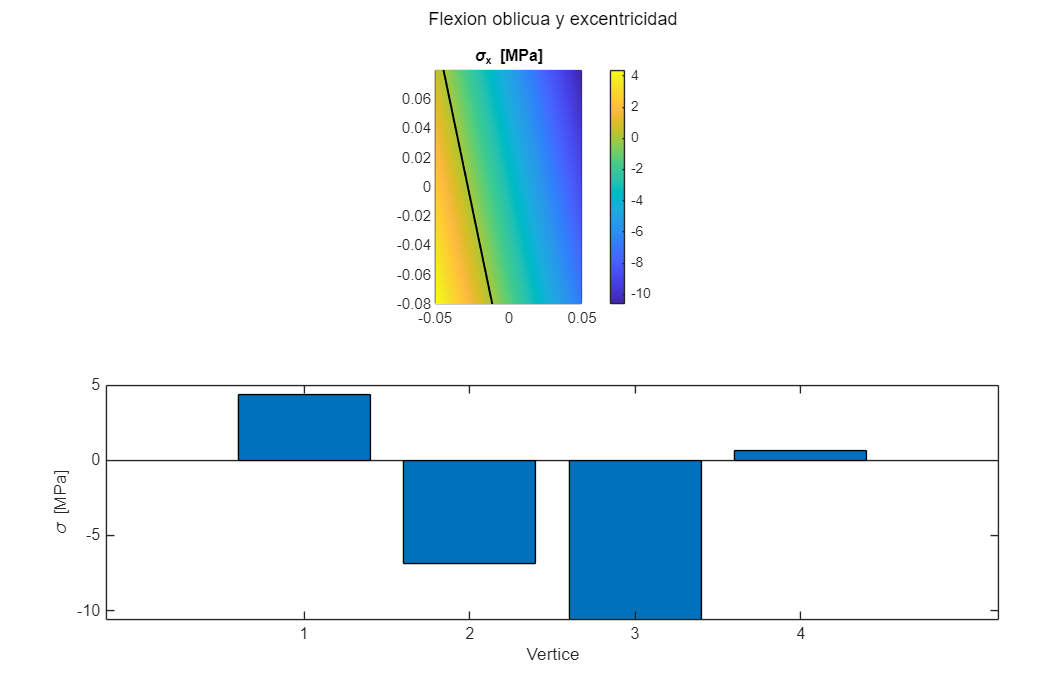

[figura,ejes]=rm_figura(2,'Flexion oblicua y excentricidad');
tr=triangulation(seccion.region); puntos=tr.Points;
sigma=N/seccion.F+(puntos-seccion.centro)*coef;
patch(ejes(1),'Faces',tr.ConnectivityList,'Vertices',puntos,'FaceVertexCData',sigma/1e6, ...
    'FaceColor','interp','EdgeColor','none');
axis(ejes(1),'equal'); colorbar(ejes(1)); title(ejes(1),'\sigma_x [MPa]');
hold(ejes(1),'on');
yy=linspace(min(puntos(:,1)),max(puntos(:,1)),100);
if abs(coef(2))>1e-12*max(abs(coef))
    zz=seccion.centro(2)-(N/seccion.F+coef(1)*(yy-seccion.centro(1)))/coef(2);
    plot(ejes(1),yy,zz,'k-','LineWidth',1.2);
elseif coef(1)~=0
    xline(ejes(1),seccion.centro(1)-N/seccion.F/coef(1),'k-');
end
xlim(ejes(1),[min(puntos(:,1)) max(puntos(:,1))]); ylim(ejes(1),[min(puntos(:,2)) max(puntos(:,2))]);
bar(ejes(2),sigmaVertices/1e6); ylabel(ejes(2),'\sigma [MPa]'); xlabel(ejes(2),'Vertice');

## Funciones utilizadas

rm_seccion: calcula propiedades geométricas. Aquí suministra el centroide y la matriz de inercias.

\: resuelve un sistema lineal. Aquí determina los dos coeficientes del campo de tensiones.

triangulation: divide una región en triángulos. Aquí permite colorear el material sin rellenar sus huecos.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Verificación de una sección poligonal, también con huecos, en régimen elástico. Incluye acoplamiento de ejes no principales mediante Iyz. No obtiene la deformada espacial completa de una viga.

Conexión con lo anterior: Reutiliza área, centroide e inercias del capítulo 3 y superposición de tensiones de los capítulos 1 y 5.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 06: calculo completado.');

Capitulo 06: calculo completado.
